clc;
global G
r_earth = 6371000; % unit = m
G = 6.6743e-11;
wgs84 = wgs84Ellipsoid('meter');

% coordinates of satellite
orbit_gracefo1 = importdata("E:/lhsPrograms/gracefo_dataset/gracefo_1B_2020-07-02_RL04.ascii.noLRI/GNV1B_2020-07-02_C_04.txt", " ", 148);
orbit_gracefo2 = importdata("E:/lhsPrograms/gracefo_dataset/gracefo_1B_2020-07-02_RL04.ascii.noLRI/GNV1B_2020-07-02_D_04.txt", " ", 148);
coor_sate1 = orbit_gracefo1.data(2548: 5378, 1: 3);
coor_sate2 = orbit_gracefo2.data(2548: 5378, 1: 3);

% coordinates of sources
lats = [0, 25, 30, 50, 60];
num = 400;
% compute the acc
los = coor_sate2(:, 1: 3) - coor_sate1(:, 1: 3);

Unrecognized function or variable 'coor_sate2'.

dis = sqrt(sum(los.^2, 2));
los = los ./ dis;
s_x = zeros(length(lats), num);
s_y = zeros(length(lats), num);
s_z = zeros(length(lats), num);
s_lon = linspace(18.35-25, 18.35+25, num);
lgd_min = zeros(length(s_lon), length(lats));
lgd_min_ind = zeros(length(lats), 1);
s_hgt = linspace(0, 0, 1);
s_mas = 100e3*100e3 * 10 * 100; % unit = kg

for h = 1: length(lats)
    s_lat = linspace(lats(h), lats(h), 1);
    
    s_coor = zeros(num, 3);
    for j = 1: num
        [s_coor(j, 1), s_coor(j, 2), s_coor(j, 3)] = geodetic2ecef(wgs84, s_lat(1), s_lon(j), s_hgt(1));
    end
    s_x(h, :) = s_coor(:, 1);
    s_y(h, :) = s_coor(:, 2);
    s_z(h, :) = s_coor(:, 3);
    
    lgd = zeros(length(coor_sate1), length(s_lon));
    for j = 1: length(s_lon)
        for i = 1: length(coor_sate1)
            pit1 = coor_sate1(i, :) - s_coor(j, :); 
            pit2 = coor_sate2(i, :) - s_coor(j, :);
            dis1 = sqrt(sum(pit1.^2, 2));
            dis2 = sqrt(sum(pit2.^2, 2));
            f = pit1 / dis1^3 - pit2 / dis2^3;

            lgd(i, j) = dot(G * f * s_mas, los(i, :));
        end
        [lgd_min(j, h), ~] = min(lgd(:, j));
    end
    [~, id_min] = min(lgd_min(:, h));
    lgd_min_ind(h) = s_lon(id_min);
end


fg_sens = new_figure;
subplot(1, 50, 1: 15)
for i = 1: length(lats)
    plot3(s_x(i, :), s_y(i, :), s_z(i, :), "*"); hold on
end
plot3(coor_sate1(:, 1), coor_sate1(:, 2), coor_sate1(:, 3), "LineWidth", 2)
axis equal
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
view([140, 30])

subplot(1, 50, 23: 50)
for i = 1: length(lats)
    plot(s_lon - lgd_min_ind(i), -lgd_min(:, i), "LineWidth", 2);  hold on;
end
grid on;
Legend = cell(length(lats), 1);
for iter = 1: length(lats)
    Legend{iter} = strcat('lat=', num2str(lats(iter)), "°");
end
legend(Legend)
box off
legend boxoff 
xlabel("Longitude [deg]")
ylabel("min(LGD)  [m/s^2]")
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
AddLetters2Plots(fg_sens, 'HShift', 0, 'VShift', 0, 'Direction', 'TopDown')

lsqr converged at iteration 1 to a solution with relative residual 0.
lsqr converged at iteration 1 to a solution with relative residual 1.3e-16.
lsqr converged at iteration 1 to a solution with relative residual 1.9e-16.
lsqr converged at iteration 1 to a solution with relative residual 1.6e-16.
lsqr converged at iteration 1 to a solution with relative residual 0.
lsqr converged at iteration 1 to a solution with relative residual 1.3e-16.
lsqr converged at iteration 1 to a solution with relative residual 2.9e-16.
lsqr converged at iteration 1 to a solution with relative residual 6.8e-17.
lsqr converged at iteration 1 to a solution with relative residual 9.2e-17.
lsqr converged at iteration 1 to a solution with relative residual 1.6e-16.
lsqr converged at iteration 1 to a solution with relative residual 2.5e-16.
lsqr converged at iteration 1 to a solution with relative residual 2.2e-16.
lsqr converged at iteration 1 to a solution with relative residual 1.5e-16.
lsqr converged at iterat

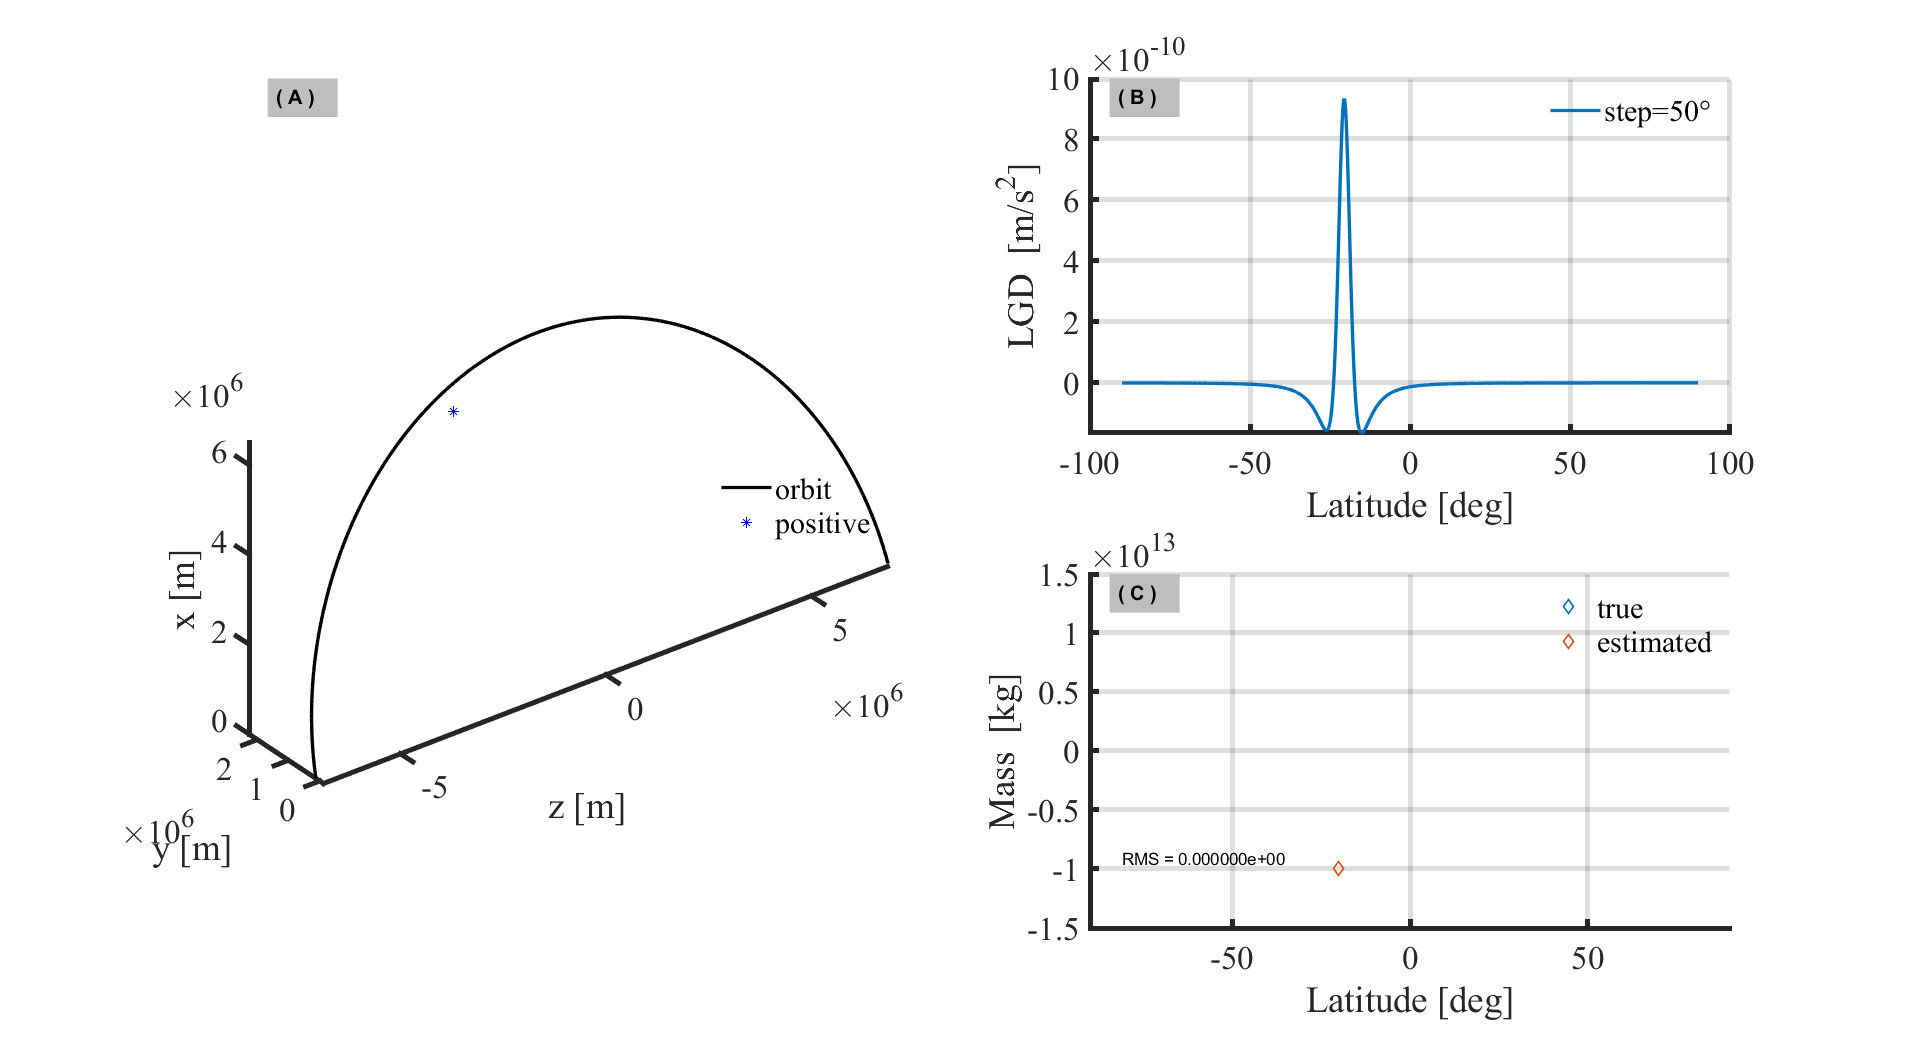

% coordinates of sources
steps = [50];

% compute the acc
los = coor_sate1(:, 1: 3) - coor_sate2(:, 1: 3);
dis = sqrt(sum(los.^2, 2));
los = los ./ dis;

lgd_min = zeros(length(s_lon), length(lats));
lgd_min_ind = zeros(length(lats), 1);
s_lon = linspace(18.35, 18.35, 1);
s_hgt = linspace(0, 0, 1);
s_mas_one = 1e13; % unit = kg
rms_es = zeros(length(steps), 1);
lgd = zeros(length(coor_sate1), length(steps));

for h = 1: length(steps)
    step = steps(h);
    s_lat = -20: step: 20;
    num = length(s_lat);
    s_mas = zeros(num, 1);
    s_coor = zeros(num, 3);
    for j = 1: num
        [s_coor(j, 1), s_coor(j, 2), s_coor(j, 3)] = geodetic2ecef(wgs84, s_lat(j), s_lon(1), s_hgt(1));
        if mod(j, 2) == 0
            s_mas(j) = s_mas_one;
        else
            s_mas(j) = -s_mas_one;
        end
    end
     
    for i = 1: length(coor_sate1)
        f = zeros(3, num);
        for j = 1: num
            pit1 = -coor_sate1(i, :) + s_coor(j, :); 
            pit2 = -coor_sate2(i, :) + s_coor(j, :);
            dis1 = sqrt(sum(pit1.^2, 2));
            dis2 = sqrt(sum(pit2.^2, 2));
            f(:, j) = pit1 / dis1^3 - pit2 / dis2^3;
        end
        lgd(i, h) = dot(G * f * s_mas, los(i, :));
    end
    s_mas_es = batch_solver(G, num, lgd(:, h), coor_sate1, coor_sate2, s_coor, los);
    
    fg_sens = new_figure;
    num = length(steps);
    subplot(2, 2, [1 3])
    plot3(coor_sate1(:, 3), coor_sate1(:, 2), coor_sate1(:, 1), "LineWidth", 2, "Color", "k"); hold on
    plot3(s_coor(2: 2: end, 3), s_coor(2: 2: end, 2), s_coor(2: 2: end, 1), "*", "Color", "red"); hold on
    plot3(s_coor(1: 2: end, 3), s_coor(1: 2: end, 2), s_coor(1: 2: end, 1), "*", "Color", "blue"); hold on
    legend(["orbit", "positive", "negative"], "Location", "east")
    legend boxoff
    axis equal
    xlabel("z [m]")
    ylabel("y [m]")
    zlabel("x [m]")
    set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
    % view([360, 60])
    
    subplot(2, 2, 2)
    plot(linspace(90, -90, length(lgd)), lgd(:, h), "LineWidth", 2);  hold on;
    grid on;
    Legend = cell(1, 1);
    Legend{1} = strcat('step=', num2str(steps(h)), "°");
    legend(Legend)
    box off
    legend boxoff 
    xlabel("Latitude [deg]")
    ylabel("LGD  [m/s^2]")
    set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
    
    subplot(2, 2, 4)
    scatter(s_lat, s_mas, "LineWidth", 1, "Marker", "diamond");  hold on;
    scatter(s_lat, s_mas_es, "LineWidth", 1, "Marker", "diamond")
    rms_es(h) = rms((s_mas_es - s_mas) ./ s_mas);
    text(min(xlim-60), min(ylim-0.4), sprintf('RMS = %e', rms_es(h)), 'Horiz','left', 'Vert','bottom')
    xlim([-90, 90])
    ylim([-1.5e13, 1.5e13])
    grid on;
    legend("true", "estimated")
    box off
    legend boxoff 
    xlabel("Latitude [deg]")
    ylabel("Mass  [kg]")
    set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3);
    AddLetters2Plots(fg_sens, 'HShift', 0, 'VShift', 0, 'Direction', 'TopDown')

    exportgraphics(fg_sens, ['../image/simu/step=', num2str(steps(h)), '.png']);
end

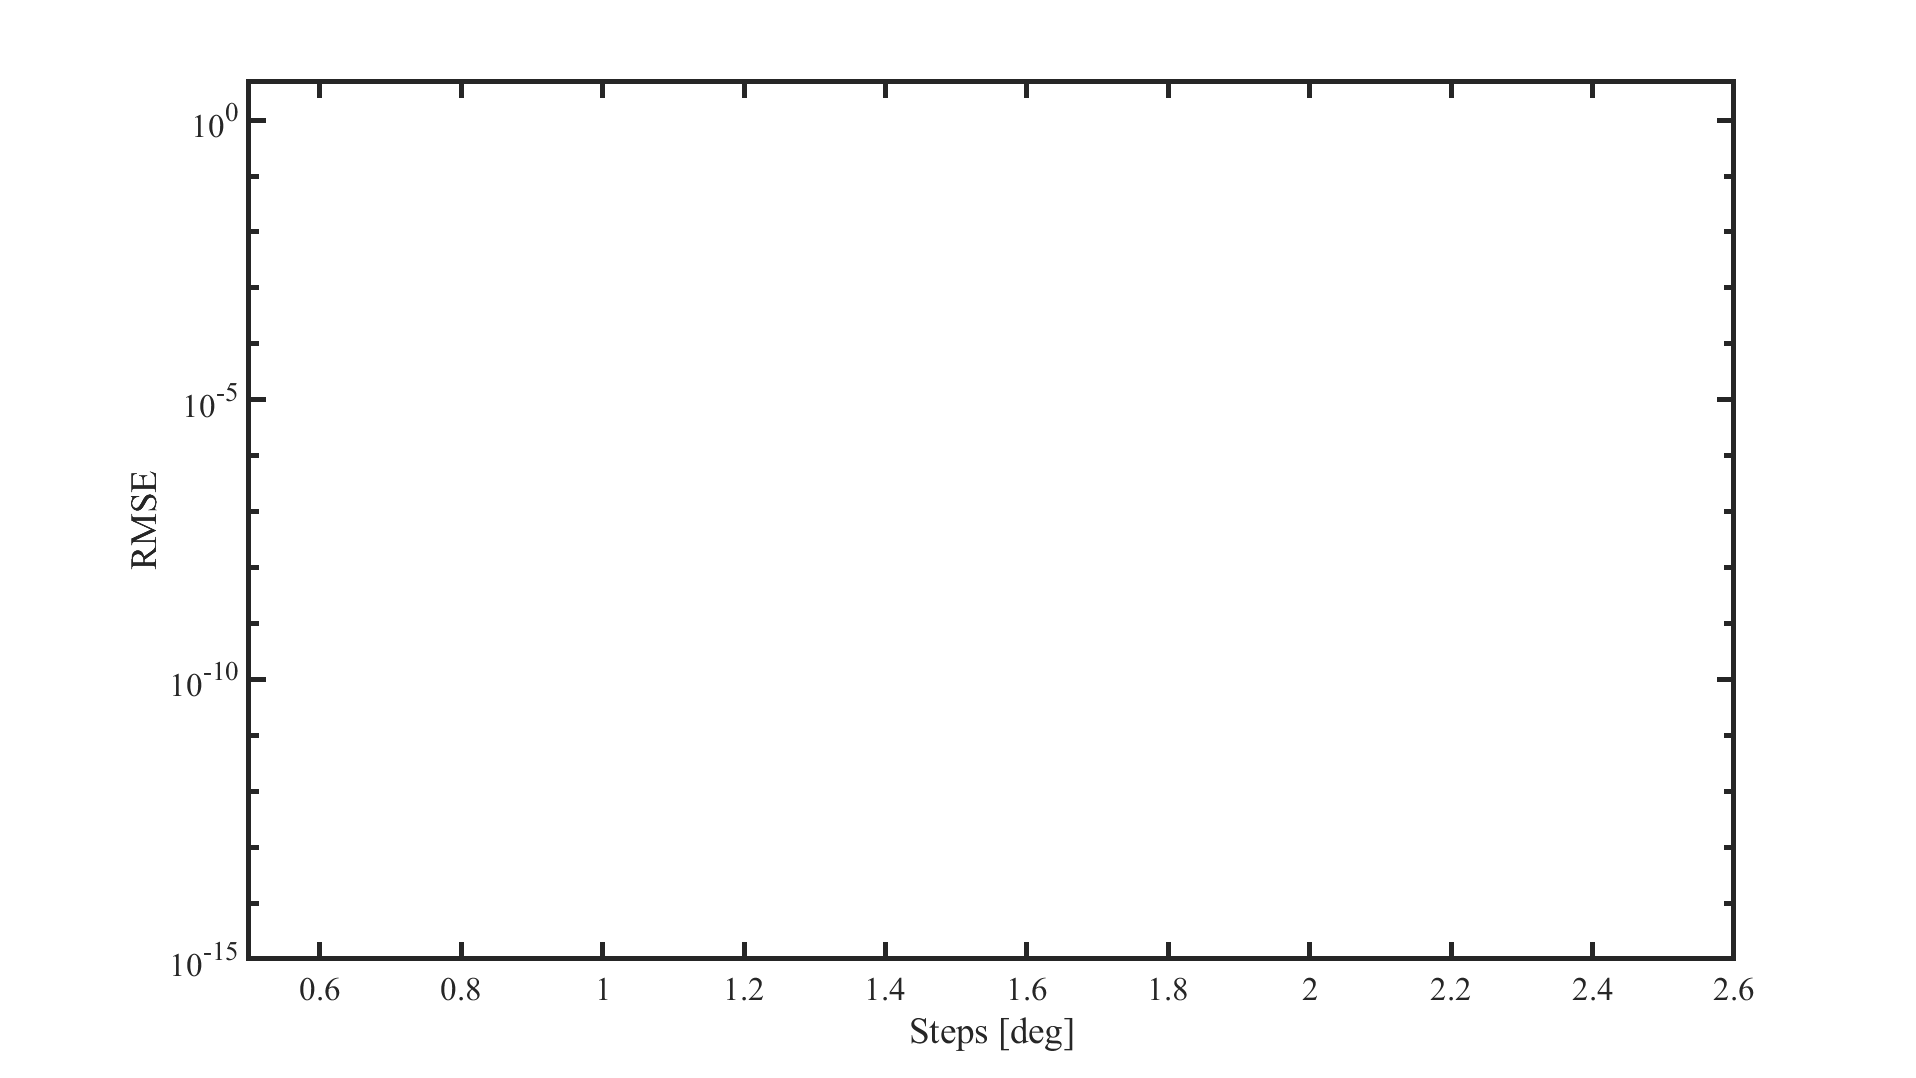

fg_sens = new_figure;
num = length(steps);
semilogy(steps, rms_es, "LineWidth", 2, "Color", "r", "Marker", "o"); hold on
xlabel("Steps [deg]")
ylabel("RMSE")
xlim([0.5, 2.6])
ylim([1e-15, 5])
set(gca, 'FontSize', 20, "fontname", "Times New Roman", "linewidth", 3); 